## ECE 537 : Assignment 8

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;
rng('default')

**Task 1: **Load the Exercise 8 data set into matlab. This data comprises a set of 100 time domain data records each comprised of approximately 10,000 samples. This data is noisy, contains measurement discontinuities and spurious data samples. Additionally, each time domain record contains the event denote by the variable event somewhere within each data record. 

**Solution:**

load('Exercise8_data.mat')

**Task 2: **Apply statistical goodness-of-fit testing to formally determine whether or not the data can be modeled as having arisen from a stationary and/or ergodic processes across any reasonable time scales.

**Solution**

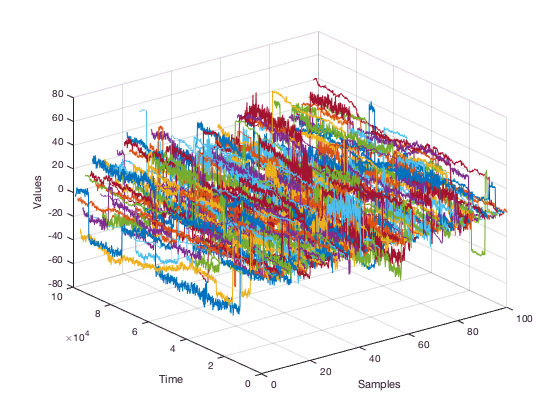

figure(1)
for i = 1:100
    plot3((i*ones(size(data(i).x))), data(i).time,movmean(data(i).x,25))
    hold on; 
    grid on; 
end
xlabel('Samples')
ylabel('Time')
zlabel('Values')


h = zeros(100,1);
g = zeros(100,1);
% % use ADF test to identify whether data can be modelled as stationarity
% for i = 1:100
%     h(i) = adftest(data(i).x);
%     g(i) = kpsstest(data(i).x);
% end_-

[y,h] = deal(cell(100,1));
data_size = 200;


%check stationarity using reshape
for i = 1:100 %number of records
    data_new = flip(data(i).x(1:10000)); %from right to left
    y{i} = reshape(data_new,[200,50]);
    for j = 1:49 %number of windows - 1
        d1 = y{i}(:,j);
        d2  = y{i}(:,j+1);
        binEdges    =  [-inf ; sort([d1;d2]) ; inf];
        binCounts1  =  histc (d1 , binEdges, 1);
        binCounts2  =  histc (d2 , binEdges, 1);     
        sumCounts1  =  cumsum(binCounts1)./sum(binCounts1);
        sumCounts2  =  cumsum(binCounts2)./sum(binCounts2); 
        sampleCDF1  =  sumCounts1(1:end-1);
        sampleCDF2  =  sumCounts2(1:end-1);
        if  j == 1
            sampleCDF1 = sampleCDF1;
        else 
            sampleCDF1 = (sampleCDF0 + sampleCDF1)/2; % averaged cdf
        end 
        h{i}(j)  = kstest2_new(sampleCDF1,sampleCDF2,data_size);
        %tstat
        sampleCDF0  = sampleCDF1;
    end 
end 
    



time- adjustment - reference with reference to the first time, (already correct)

cubic spline interpolation

distribution freee test is weaker since analytical information is not present, stricter test would include the noise.

stochastic samplings interpolate and then get to fix time. 

Stationarity for each record independently . Windows of data , do a goodness of fit. reshape function, pdf, anderson darling , KS test,

for all the samples that stationary do they converge to the sample distribution. stationary distrbution 

histogram between difference in time stamp

histogram of samples, less than 64 values in sample than it is coarse quantized

Change the shape of te

New signal out of samples, samplerate is changed, frequencies I can resolved in original signal is different from signal frequences i can resolve in new signal

no easy way to get back to x(t), depends on property of signal, less than 64 steps , information lossy process, no easy way to recover original signal If > 64 steps , then we can do approximately, many idffierent signals can give rise to the same measurement, uncertainity is more. Knowing a lot more of the underlying process, if we know the frequency components.

if signal is more complex than 2 sinusoids + white noise then no soluton for quantization.

Remove that record, NAN 57 , fields out of range, systems recording the data,

distributiion free test, 

window could take into account transtrient behaviour from left to right

wavelet is 

window of data, sampling the event with respect to the same sampling period as original record

removing time information will make the step meaningless.

Assumption medium 

median is the good estimation of the outlier

configured and tuned to pick the outlier

median filter is designed to remove the spikes

Assumption wavelets

Wavelets can create spurious spikes due to edge effects so you might need to do median filter.

Wavelets is a way to denoise non-stationary time series data, classical way is use to digital filter but that doesnt work well for non-stationary data.

**Task 3: **Determine whether the data comprises constant sampling intervals or stochastic sampling intervals. Discuss the data analysis differences and distinctions that arise for these two cases. In the case of stochastic sampling develop and apply an appropriate methodology to enable correct data analysis and discuss why not correcting for the stochastic sampling is problematic. Would it be problematic in all cases?

% To determine whether the data comprises of constant sampling intervals or
% stochastic sampling intervals

%the data number 57 cannot be interpolated due to NaN time instants.Hence
%it is to be discarded

data_d = data;
data_d(57) = [];
diff_time = cell(99,1);
for i  = 1:99
    data_time = data_d(i).time;
    diff_time{i}  = diff(data_time);
    if numel(unique(diff_time{i})) == 1
        s(i) = 0;
    else 
        s(i) = 1; %stochastically sampled.
    end
end 

%develop and apply an appropriate methodology to enable correct data analysis 
for i  = 1:99
    event_struct(i).x = event;
    event_struct(i).time = event;
    min_sample_period = min(diff_time{i}(diff_time{i}>0));
    [data_resampled(i).x, data_resampled(i).time] = resample(data_d(i).x,data_d(i).time,1/min_sample_period,'spline');
end
    

**Task 4:** Determine whether any of the data records contain coarsely quantized data and discuss the impacts and concerns that arise for coarsely quantized data sets. How would you correct for coarsely quantized data and is it correctable?

for i = 1:100
    data_sample = data(i).x;
    coarse(i) = length(unique(data_sample));
    if coarse(i) > 64
        c(i) = 0;
    else 
        c(i) = 1;
    end
end

Comments:

**Task 5:** Apply median filtering to remove all spurious data samples. Discuss the assumption that median filtering makes.

for i = 1:99
    data_resampled_median{i} = movmedian(data_resampled(i).x,101,'Endpoints','discard');
end

Comments: 

**Task 6: **Use the waveletAnalyzer tool to explore how wavelet denosing can be applied to denoise the data records.

dx1 = data(1).x;
dt1 = data(1).time;

https://www.mathworks.com/help/wavelet/ref/waveletsignaldenoiser-app.html
https://www.mathworks.com/help/wavelet/ug/denoise-a-signal-with-the-wavelet-signal-denoiser.html

**Task 7:** Implement a full wavelet denosing approach for the full set of 100 data records. 

t1 = wdenoise(dx1)

Undefined function 'wdenoise' for input arguments of type 'double'.

https://www.mathworks.com/help/wavelet/ref/wdenoise.html#d120e91379
https://www.mathworks.com/help/wavelet/ug/wavelet-denoising.html

Discuss whether or not (and why) wavelet denoising provides a improved denosing approach over classical noise filtering methods for the given data records i.e., If you applied a standard low pass filtering approach to the data what would the results be?

**Task 8:** Post denoising, develop and apply an appropriate methodology for correcting for the discontinuities that arise within the data records and discuss when such corrections are appropriate and when they are not. 

Would your developed approach continue to work for real-time (streamed) data? Discuss why or why not and the issues and complexities that real-time (streamed) data introduces.

**Task 9:** Apply matching filtering to locate when the time domain event described by the variable event exists within each of the given data records.

https://www.mathworks.com/help/phased/ref/phased.matchedfilter-system-object.html


Discuss the assumptions underlying matched filtering and which situations it will work in and which it will not.

 function h = kstest2_new(sampleCDF1,sampleCDF2,N)
     alpha  =  0.05; %significance value
     deltaCDF  =  abs(sampleCDF1 - sampleCDF2);
     KSstatistic   =  max(deltaCDF);
     n1     =  N;
     n2     =  N;
     n      =  n1 * n2 /(n1 + n2);
     lambda =  max((sqrt(n) + 0.12 + 0.11/sqrt(n)) * KSstatistic , 0);
     j       =  (1:101)';
     pValue  =  2 * sum((-1).^(j-1).*exp(-2*lambda*lambda*j.^2));
     pValue  =  min(max(pValue, 0), 1);
     h  =  (alpha >= pValue);
 end